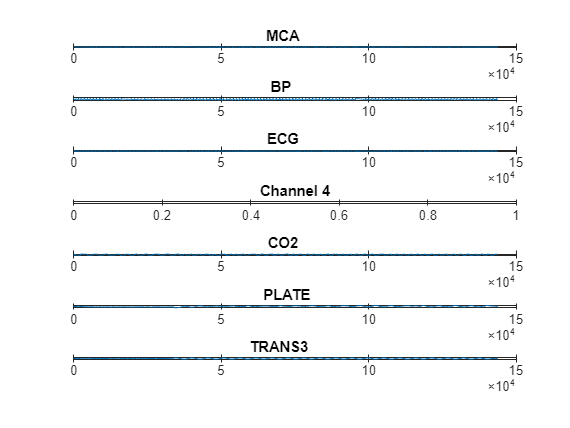

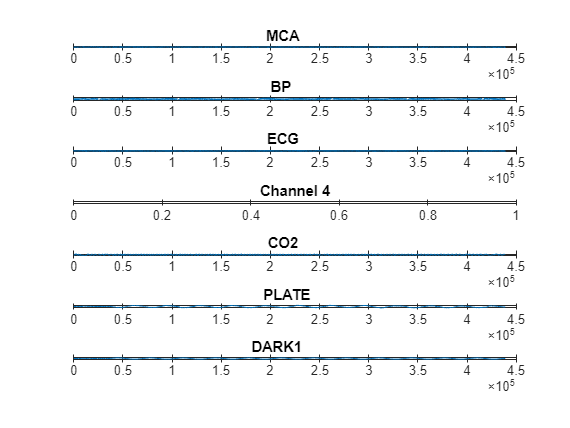

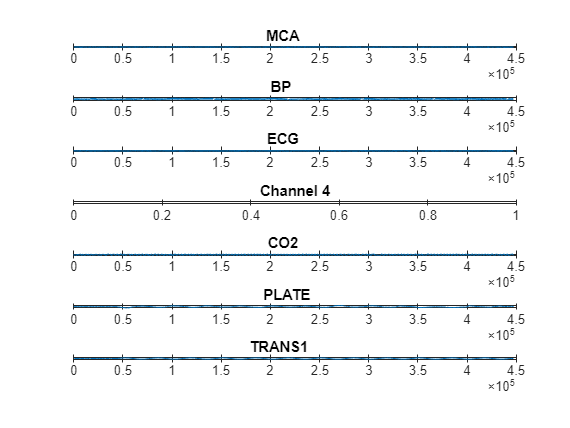

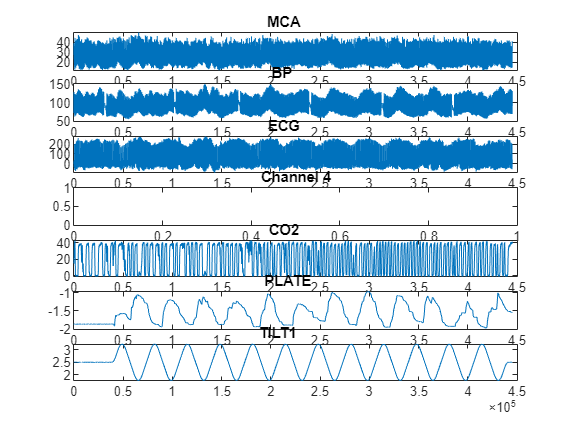

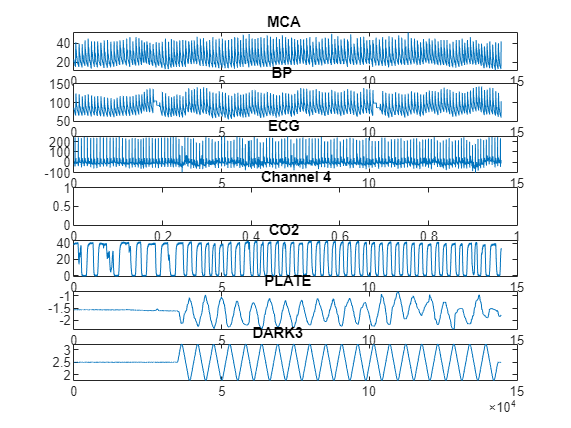

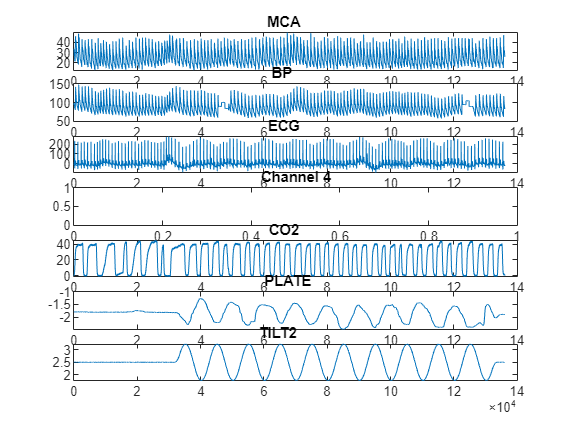

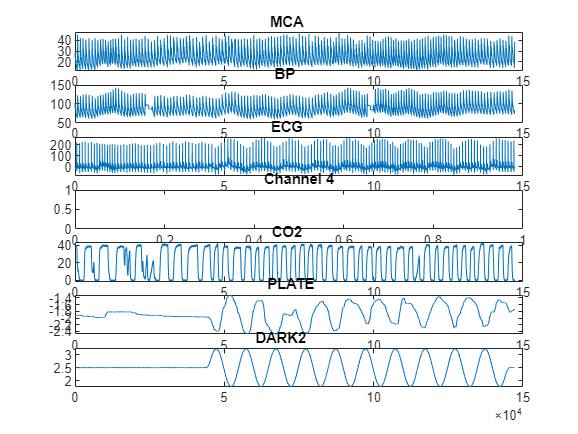

n = 7;
m = 1;
p = 1;
namevar = 2;
data = data_block1;
tickblock = comtick_block1;
times = ticktimes_block1;
i = 1;
name = comtext_block1(namevar,1:14); 
titles = titles_block1(i,1:9); % MCA, MP, ECG, etc.
titlevar = 1;
chairpos = titles_block1(7,1:9); % Fixing graph #7

while p <= n % plots each test
    a = tickblock(m,1);
    b = tickblock(m+2,1);
    m = m + 3;
    figure("Name",name);
    for i = 1:n % plots each graph in test
        subplot(n,1,i);
        plot(data(i,a:b))
        if titlevar == 8;
            titlevar = 1;
        end
        title(titles_block1(titlevar,1:9))
        titlevar = titlevar + 1;
        i = i + 1;
    end
    title(name)
    p = p + 1;
    namevar = namevar + 3; %Updates each title
    name = comtext_block1(namevar,1:14); 
end